A script to examine the behavior of a modified enzyme-producing E coli model under a variety of conditions in order to describe the optimal conditions

The model produces enzyme at a rate (alpha) proportional to the biomass production rate. This is the "proportional" strategy from models/generation/buildCometsModels. So 

    V_carbon = (1 - alpha) * V_biomass + alpha * V_enzyme  (TODO: Confirm implementation actually has this effect)

Tasks:

- plots: 

-     log biomass / time for high vs low enzyme rate

-     yield / alpha

-     growth rate / alpha

-    max rate / final yield

Implementation of rate:

- Define maximal enzyme expression rate VE_MAX

-         First pass: VE_MAX = VBIOMASS_MAX

- define alpha as millimoles of enzyme produced per gram biomass per hour

- Add/modify reactions

-     create 1 unit of biomass pseudometabolite in the original objective reaction

-     [VE_MAX * alpha * constant_i * AminoAcid_i ] -> Enzyme(c)

-     Enzyme(c) + biomass_pesudo -> VE_MAX * Enzyme(e)

%%Variables to control which parts of this script execute
%Comment out the assignment to True in order to skip a block
refreshmodel = false; refreshbt = false; refreshya = false; refreshplots = false; buildMultiCelluloseTable = false;

refreshplots = true;

%Reload the E coli model
refreshmodel = true;

%Biomass / Time
%refreshbt = true;
useOnlyBTModels = true;
%Yield / Alpha
%refreshya = true;
buildMultiCelluloseTable = true;

**Variables**

%%STRATEGY VARIABLES
v.defaultbound = 10; %default exchange upper bound
v.maxEnzymeRate = 1; %maximum enzyme:biomass ratio by weight for fixed production. 1:1 w/ alpha=1 should mean half of all amino acids go into enzyme
v.alpha = 0.1; %fixed percentage of the maximum enzyme rate being expressed


%%ENZYME VARIABLES. See https://www.brenda-enzymes.org/enzyme.php?ecno=3.2.1.4
%values used: wild-type T.ressei on 4-methylumbelliferyl cellobioside. https://www.brenda-enzymes.org/literature.php?e=3.2.1.4&r=737187
v.kcat_cel = 0.01; %mmol converted / mmol enzyme / second  %TODO: Confirm units
v.km_cel = 0.125; %Units = mmoles/cm^3

%%Glucose variables
v.km_glc = 0.01; %millimoles/cm^3.
v.vmax_glc = 10;
v.glcpercellulose = 218.2;%how many units of glucose get released per unit cellulose? 1:1 assumes units are by weight
    %Avicel degree of polymerization cite : https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3217711/
v.biomassperglc = 1/(1.447e9); %how many units of biomass are produced for every unit glc consumed?
    %weight of E coli / weight of glc molecule = 433fg / (2.992e-22g) = 4.33e-13 / (2.992e-22) = 1.447e9
v.glcuptakerate = -10; %bound for the GLC import reaction
                         %This should be higher than required for max enzyme production


%Enzyme variables v 2- set high to check that everything works OK
%v.kat = 100;
%v.km = 0.0001;

%%WORLD/LAYOUT VARIABLES
v.xdim = 1;
v.ydim = 1;
v.diff_cel = 0; %Diffusion constants
v.diff_enz = 1e-6; %Default is 1e-6;
v.diff_glc = 1e-6;
%v.enzdecayrate = 0; %degradation of enzyme over time
%v.deathrate = 0;
%v.enzymeperglc = 0.05; %how many units of enzyme are produced for every unit glc consumed?
v.initcellulose = 1;
v.initglc = 1e-8; %needed to bootstrap production
v.initmedia = 1; %amount of all other media added

%%COMETS EXECUTION VARIABLES
v.maxcycles = 200;
v.timestep = 3; %1/(60*60); %1/3600 hours = 1 second. CAUTION: Make sure this agrees with the units in kcat.
v.filepath = 'C:\sync\biomes\cellulose\optima\temp';
v.writemedialog = true;
v.writebiomasslog = true;
v.writefluxlog = false;
v.lograte = 1;
v.maxspacebiomass = 1000;
v.spaceWidth = 1; %1cm, so v=1mL and most media are 1 millimolar
v.lograte = 2;

v_default = v;

%%DEFAULT MODEL
if refreshmodel
    %model_default = load('C:\sync\biomes\models\ecoli_core_model_norm.mat'); %model with metabolite names normalized
    model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
    model_default = model_default.iJO1366;
end

**Biomass over time**

v = v_default;
%alphas = [0.05 0.1 0.5 1:8];
%alphas = 0.05:0.05:0.3;
%alphas = [0.00001 0.0001 0.001 0.01 0.1 0.25 0.5 0.75 1 2];
%alphas = 5:2:25;
%alphas = 9;
%alphas = [0.025 0.05 0.1:0.1:1.5];
alphas = [0.5:0.05:0.8 0.9:0.1:1.6];

if refreshbt
    btmodels = cell(length(alphas),1);
    for i=1:length(alphas)
    a = alphas(i);
        v.alpha = a;
        mname = ['a = ' num2str(a)];
        model = buildEcoliModel(v,model_default,mname);
        btmodels{i} = model;
    end
    btmodels = executeModels(btmodels);
end

**Multiple Cellulose Amounts**

if buildMultiCelluloseTable
    cel_amts = [0.1 0.5 1 2];
    %varnames = {'cellulose','alpha','model'};
    %celtab = array2table(nan(length(cel_amts) * length(alphas),length(varnames)),'VariableNames',varnames);
    c = [];
    a = [];
    m = {};
    for i = 1:length(cel_amts)
        v.initcellulose = cel_amts(i);
        for j=1:length(alphas)
            alpha = alphas(j);
            v.alpha = alpha;
            mname = ['a = ' num2str(alpha)];
            model = buildEcoliModel(v,model_default,mname);
            model = executeModel(model);
            c(end+1) = cel_amts(i);
            a(end+1) = alphas(j);
            m{end+1} = model;
        end
    end
    celtab = table(c',a',m','VariableNames',{'cellulose','alpha','model'}); 
end

**Yield over alpha**

%NOTE: Make sure that all models have enough time to run to completion
v = v_default;
%alphas = [0.005 0.05 0.1 0.25 0.5 0.75 1 1.25 1.5 1.75 2 2.5 3 4 5];

%set up V
v.writebiomasslog = true;
v.lograte = 10;

if refreshya
    yamodels = cell(length(alphas),1); %"ya" == "Yield/Alpha"
    for i=1:length(alphas)
    a = alphas(i);
        v.alpha = a;
        mname = ['a = ' num2str(a)];
        model = buildEcoliModel(v,model_default,mname);
        yamodels{i} = model;
    end
    yamodels = executeModels(yamodels);
end

%-----------------
if useOnlyBTModels
    yamodels = btmodels;
end

**Exponential Phase Growth Rate**

ramodels = yamodels; %"RA" = "Rate / Alpha"


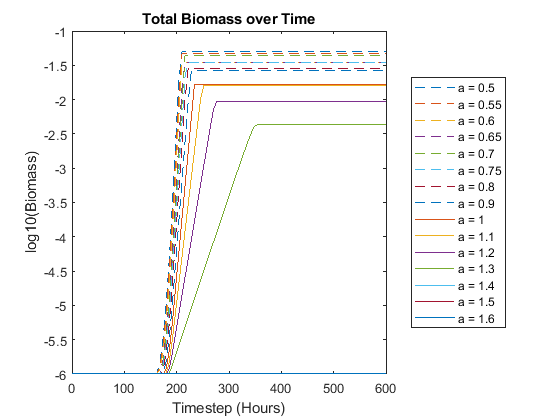

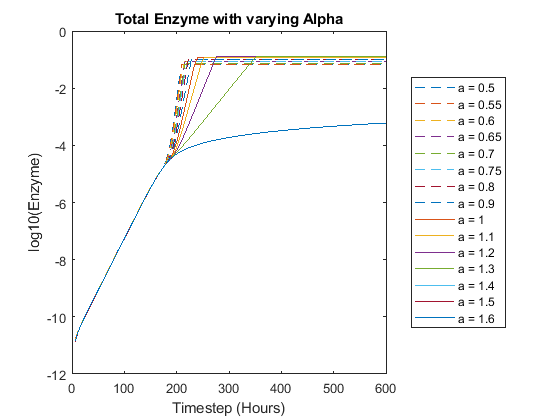

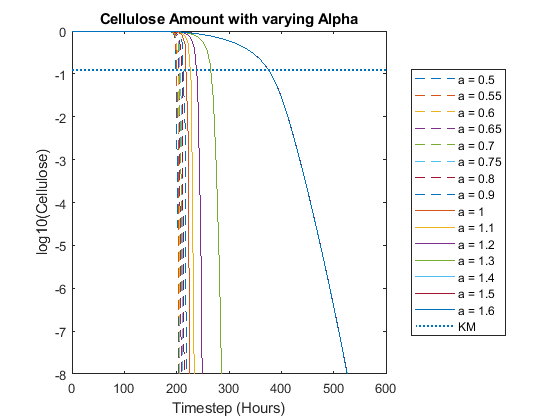

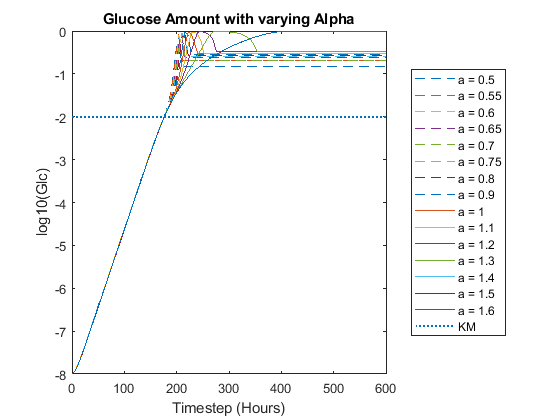

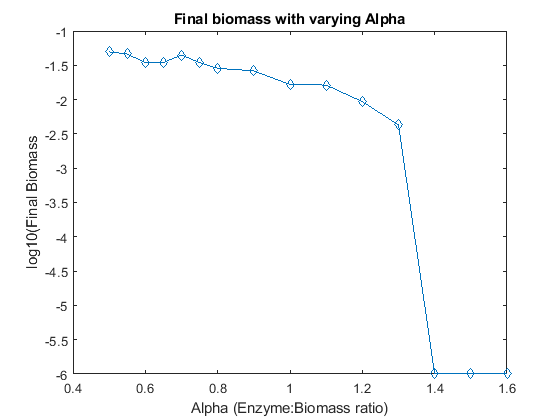

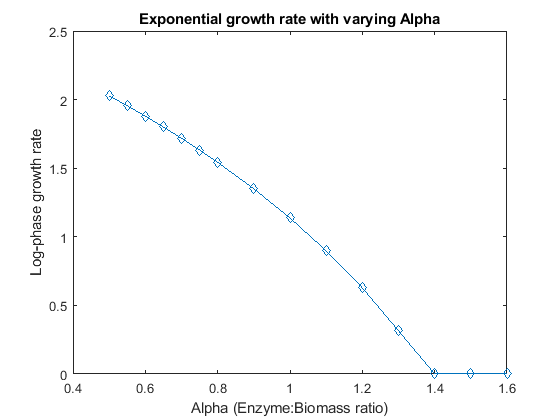

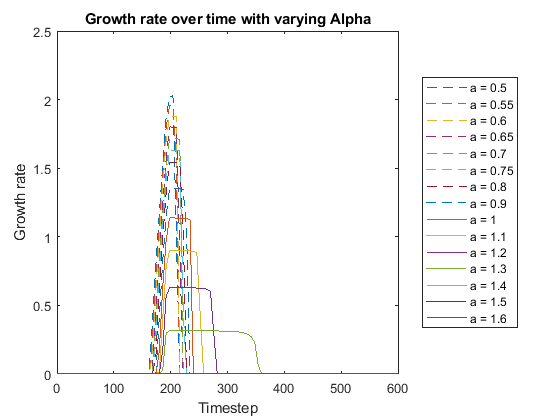

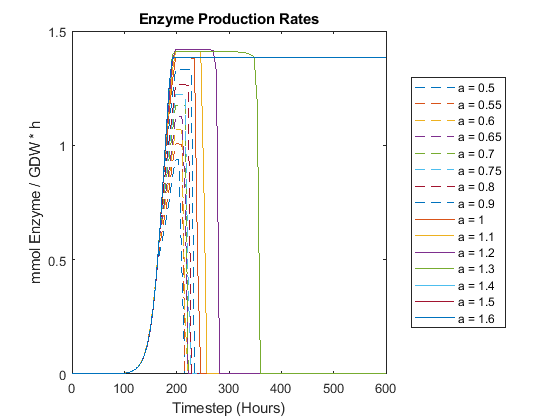


if refreshplots
[p, btmodels] = plotBiomassOverTime(btmodels);
[p5, btmodels] = plotEnzymeTimecourse(btmodels);
[p6, btmodels] = plotCelluloseTimecourse(btmodels);
[p7, btmodels] = plotGlucoseTimecourse(btmodels);
[p2, yamodels] = plotYAModels(yamodels);
[p3, ramodels] = plotRAModels(ramodels); 
[p4, ramodels] = plotRates(ramodels);
[p8, btmodels] = plotEnzRates(btmodels);
[p9, btmodels] = plotGlcRates(btmodels);
[p10, btmodels] = plotRateOverYield(btmodels);
end

% function [figure3, models] = plotRAModels(ramodels)
% %plot k as in the exponential growth formula x(t) = x(0)e^kt
% models = executeModels(ramodels);
% 
% biodat = zeros(length(models),1);
% xdat = zeros(length(models),1);
% for i = 1:length(models)
%     xdat(i) = models{i}.v.alpha;
%     %get the rate a few steps before the curve levels off
%     model = models{i};
%     deltas = log(model.biomass(2:end)) - log(model.biomass(1:end-1));
%     finish = find(deltas > 0, 1, 'last');
%     if finish == length(deltas)
%         finish = length(deltas) - round(length(deltas)/10);
%     end
%     %steps = round(finish/10); %step back 1/10th of the way
%     %drange = 1; %use this to check a few different deltas
%     %a = max([finish-steps-drange 1]);
%     %b = min ([finish-steps+drange length(deltas)]);
%     %d = mean(deltas(a:b)); 
%     %biodat(i) = d;
%     biodat(i) = max(deltas);
% end
% figure3 = figure;
% 
% % Create axes
% axes3 = axes('Parent',figure3);
% hold(axes3,'on');
% % Create plot
% plot(xdat,biodat,'DisplayName','Rate','Marker','diamond');
% 
% % Create labels
% xlabel('Alpha (Enzyme:Biomass ratio)');
% ylabel('Log-phase growth rate');
% title('Exponential growth rate with varying Alpha');
% 
% % Uncomment the following line to preserve the Y-limits of the axes
% %ylim(axes3,[0 3.5]);
% box(axes3,'on');
% 
% end
% 
% %--------------------------------------------------------------------------------
% function [figure10, models] = plotRateOverYield(btmodels)
% %plot k as in the exponential growth formula x(t) = x(0)e^kt
% models = executeModels(btmodels);
% 
% biodat = zeros(length(models),1);
% xdat = zeros(length(models),1);
% alphas = zeros(length(models),1);
% for i = 1:length(models)
%     alphas(i) = models{i}.v.alpha;
%     %get the rate a few steps before the curve levels off
%     model = models{i};
%     deltas = log(model.biomass(2:end)) - log(model.biomass(1:end-1));
%     finish = find(deltas > 0, 1, 'last');
%     if finish == length(deltas)
%         finish = length(deltas) - round(length(deltas)/10);
%     end
%     %steps = round(finish/10); %step back 1/10th of the way
%     %drange = 1; %use this to check a few different deltas
%     %a = max([finish-steps-drange 1]);
%     %b = min ([finish-steps+drange length(deltas)]);
%     %d = mean(deltas(a:b)); 
%     %biodat(i) = d;
%     biodat(i) = log10(max(deltas));
%     xdat(i) = log10(model.biomass(end));
% end
% figure10 = figure;
% 
% % Create axes
% axes10 = axes('Parent',figure10);
% hold(axes10,'on');
% % Create plot
% plot(xdat,biodat,'DisplayName','Rate','Marker','diamond');
% 
% datalabels = cellstr( num2str(alphas) );
% text(xdat,biodat, datalabels, 'VerticalAlignment','bottom','HorizontalAlignment','left');
% 
% % Create labels
% xlabel('Final Biomass ( Log10 GDW )');
% ylabel('Log10 (Max Growth Rate');
% title('Growth Rate Over Final Yield [Labels = alpha]');
% 
% % Uncomment the following line to preserve the Y-limits of the axes
% %ylim(axes3,[0 3.5]);
% box(axes10,'on');
% 
% end
% 
% %--------------------------------------------------------------------------------
% 
% function [figure4, models] = plotRates(ramodels)
% %the instantaneous growth rate of each model
% models = executeModels(ramodels);
% 
% biodat = zeros(length(models{1}.timestep),length(models)); %y axis
% xdat = zeros(length(models{1}.timestep),length(models));
% for i = 1:length(models)
%     xdat(1:end,i) = models{i}.timestep * models{i}.v.timestep;
%     model = models{i};
%     deltas = log(model.biomass(2:end)) - log(model.biomass(1:end-1));
%     biodat(2:end,i) = deltas; %first delta is left as 0.
% end
% figure4 = figure;
% 
% % Create axes
% axes4 = axes('Parent',figure4);
% hold(axes4,'on');
% % Create plot
% plot4 = plot(xdat,biodat,'Parent',axes4);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot4(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep');
% ylabel('Growth rate');
% title('Growth rate over time with varying Alpha');
% box(axes4,'on');
% legend4 = legend(axes4,'show');
% set(legend4,'Location','eastoutside');
% 
% % Uncomment the following line to preserve the Y-limits of the axes
% % ylim(axes1,[0 0.0001]);
% box(axes4,'on');
% 
% end
% %--------------------------------------------------------------------------------
% 
% function [figure2, models] = plotYAModels(yamodels)
% models = executeModels(yamodels);
%     
% biodat = zeros(length(models),1);
% xdat = zeros(length(models),1);
% for i = 1:length(models)
%     biodat(i) = log10(models{i}.biomass(end));
%     xdat(i) = models{i}.v.alpha;
% end
% 
% figure2 = figure;
% 
% % Create axes
% axes2 = axes('Parent',figure2);
% hold(axes2,'on');
% % Create plot
% plot(xdat,biodat,'DisplayName','Final Biomass','Marker','diamond');
% 
% % Create labels
% xlabel('Alpha (Enzyme:Biomass ratio)');
% ylabel('log10(Final Biomass');
% title('Final biomass with varying Alpha');
% 
% %ylim(axes2,[0 0.005]);
% box(axes2,'on');
% end
% 
% %--------------------------------------------------------------------------------
% 
% % function model = buildToyModel(v,description)
% % %Build the toy model. Most bounds are not set here because they will vary depending on the strategy.
% % model = createModel();
% % model = addReaction(model, 'produce_biomass', {'biomass_pseudo','enzyme','glucose'}, [(1-v.alpha) * v.biomassperglc, v.alpha * v.biomassperglc, -1], 0); %%include a pseudomet so this is separate from the glc exchange rxn
% % %TODO: Units of enzyme are now relative to weight of biomass, not in concentration units. Remember/fix this when talking about KM /kcat values etc
% % model = addReaction(model, 'objective_biomass', {'biomass_pseudo'}, -1, 0);
% % model = addExchangeRxn(model,{'enzyme','glucose',},[-v.defaultbound,-v.defaultbound],[v.defaultbound,v.defaultbound]);
% % model = setBiomassRxn(model,'objective_biomass');
% % model.c(stridx('objective_biomass',model.rxns)) = 1;
% % model.description = description;
% % model.v = v;
% % end
% 
% 
% 
% %--------------------------------------------------------------------------------
% 
% function [figure1, models] = plotBiomassOverTime(models)
% models = executeModels(models);
% 
% %assemble data
% nrecords = length(models{1}.timestep);
% biodat = zeros(nrecords,length(models));
% tdat = zeros(nrecords,length(models));
% for i = 1:length(models)
%     biodat(1:end,i) = models{i}.biomass;
%     tdat(1:end,i) = models{i}.timestep * models{i}.v.timestep;
% end
% 
% figure1 = figure;
% % Create axes
% axes1 = axes('Parent',figure1,...
%     'Position',[0.128692810457516 0.11 0.775 0.815]);
% hold(axes1,'on');
% 
% % Create the log(biomass)/time plot
% plot1 = plot(tdat,log10(biodat),'Parent',axes1);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot1(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep (Hours)','HorizontalAlignment','center');
% ylabel('log10(Biomass)','HorizontalAlignment','center');
% title('Total Biomass over Time');
% box(axes1,'on');
% legend1 = legend(axes1,'show');
% set(legend1,'Location','eastoutside');
% 
% end
% 
% %--------------------------------------------------------------------------------
% 
% function models = executeModels(models)
% %if models haven't been run yet, run them and attach the biomass log
% for i = 1:length(models)
%     if ~isfield(models{i},'biomass')
%         models{i} = executeModel(models{i});
%     end
% end
% end
% 
% %--------------------------------------------------------------------------------
% 
% %run the model and attach its biomass log to it
% function model = executeModel(model)
% layout = buildToyLayout(model);
% createCometsFiles(layout,model.v.filepath,'layout_temp.txt');
% runCometsOnDirectory(model.v.filepath);
% 
% tab = parseBiomassLog([model.v.filepath '\log_biomass.m']);
% model.biomass = tab.biomass; %no need to sum if there's no biomass diffusion
% model.timestep = tab.t;
% 
% if model.v.writemedialog
%     media = parseMediaLog([model.v.filepath '\log_media.m'],{'enzyme_e', 'cellulose', 'glc__D_e'});
%     model.enzyme_amt = zeros(length(model.timestep),1);
%     model.cellulose_amt = zeros(length(model.timestep),1);
%     model.glc_amt = zeros(length(model.timestep),1);
%     for i = 1:length(model.timestep)
%         time = model.timestep(i);
%         enzrows = (media.t == time) & strcmp(media.metname,'enzyme_e');
%         celrows = (media.t == time) & strcmp(media.metname,'cellulose');
%         glcrows = (media.t == time) & strcmp(media.metname,'glc__D_e');
%         subtab = media(enzrows,:);
%         model.enzyme_amt(i) = sum(subtab.amt);
%         subtab = media(celrows,:);
%         model.cellulose_amt(i) = sum(subtab.amt);
%         subtab = media(glcrows,:);
%         model.glc_amt(i) = sum(subtab.amt);
%     end
% end
% 
% end
% 
% %--------------------------------------------------------------------------------
% 
% function layout = buildToyLayout(model)
% %Create a layout containing the given model, including the standard enzyme reaction
% v = model.v;
% layout = createLayout();
% layout = addModel(layout,model);
% layout = addExternalReaction(layout,'degrade_cellulose',{'cellulose','glc__D_e'},[(-1/v.glcpercellulose) 1],'enzyme', 'enzyme_e', 'k', v.kcat_cel, 'km', v.km_cel);
% layout = setDims(layout,v.xdim,v.ydim);
% layout = setInitialPop(layout,'colonies',1e-6,false);
% 
% media = {'ca2_e', 'cbl1_e', 'cl_e', 'co2_e', 'cobalt2_e', 'cu2_e', 'fe2_e', 'fe3_e', 'h_e', 'h2o_e', 'k_e', 'mg2_e', 'mn2_e', 'mobd_e', 'na1_e', 'nh4_e', 'ni2_e', 'o2_e', 'pi_e', 'sel_e', 'slnt_e', 'so4_e', 'tungs_e', 'zn2_e'};
% 
% for i = 1 : length(media)
%  layout = setInitialMedia(layout,media{i},1);
% end
% layout = setMedia(layout,'cellulose',v.initcellulose);
% layout = setInitialMediaInCell(layout,ceil(v.xdim/2),ceil(v.ydim/2),'glc__D_e',v.initglc);
% %layout = setMedia(layout,'enzyme_e',0);
% 
% layout = setDiffusion(layout,'cellulose', v.diff_cel);
% layout = setDiffusion(layout,'enzyme_e', v.diff_enz);
% layout = setDiffusion(layout,'glc__D_e', v.diff_glc);
% 
% if (~exist(v.filepath,'dir'))
%     mkdir(v.filepath);
% end
% 
% layout.params.maxSpaceBiomass = v.maxspacebiomass;
% layout.params.writeBiomassLog = v.writebiomasslog;
% layout.params.writeMediaLog = v.writemedialog;
% layout.params.writeFluxLog = v.writefluxlog;
% layout.params.biomassLogRate = v.lograte;
% layout.params.mediaLogRate = v.lograte;
% layout.params.fluxLogRate = v.lograte;
% layout.params.biomassLogName = [v.filepath '\log_biomass.m'];
% layout.params.mediaLogName = [v.filepath '\log_media.m'];
% layout.params.fluxLogName = [v.filepath '\log_flux.m'];
% layout.params.maxCycles = v.maxcycles;
% layout.params.timeStep = v.timestep;
% layout.params.pixelScale = 10;
% layout.params.spaceWidth = v.spaceWidth;
% end
% 
% %--------------------------------------------------------------------------------
% 
% function model = buildEcoliModel(v,defaultmodel,description)
% model = defaultmodel;
% 
% %add biomass pseudometabolite to the biomass reaction
% %model = addMetabolitesToRxn(model,'biomass_pseudo',find(model.c),1);
% 
% %create the enzyme reaction
% %include ala__d_C?
% aminos = {'ala__L_c' 'arg__L_c' 'asn__L_c' 'asp__L_c' 'cys__L_c' 'gln__L_c' 'glu__L_c'...
%     'gly_c' 'his__L_c' 'ile__L_c' 'leu__L_c' 'lys__L_c' 'met__L_c' 'pro__L_c' ...
%     'ser__L_c' 'thr__L_c' 'trp__L_c' 'tyr__L_c' 'val__L_c'}; %array of amino acid names
% % aminos = {'ala-L[c]' 'arg-L[c]' 'asn-L[c]' 'asp-L[c]' 'cys-L[c]' 'gln-L[c]' 'glu-L[c]'...
% %    'gly[c]' 'his-L[c]' 'ile-L[c]' 'leu-L[c]' 'lys-L[c]' 'met-L[c]' 'pro-L[c]' ...
% %    'ser-L[c]' 'thr-L[c]' 'trp-L[c]' 'tyr-L[c]' 'val-L[c]'}; %array of amino acid names
% 
% %%proportional makeup of enzyme for each AA 
% %prop = -1 / length(aminos);
% %aminocoeffs = ones(length(aminos)) * prop; 
% %%this needs to be scaled: the sume here = -1, but the sum of fluxes for the objective = -5.16532
% 
% %Set AA makeup for enzyme equal to biomass
% aminoidxs = zeros(1,length(aminos));
% for i = 1:length(aminos)
%     aminoidxs(i) = stridx(aminos{i},model.mets,false);
% end
% aminocoeffs = model.S(aminoidxs,find(model.c));
% 
% %rates = aminocoeffs * v.maxEnzymeRate * v.alpha;
% rates = aminocoeffs;
% rates(length(rates)+1) = 1;
% reactants = [aminos 'enzyme_c'];
% model = addReaction(model,'produce_enzyme',reactants, rates, 0);
% 
% %Create amino acid exchange reactions
% createAAExchanges = false;
% if createAAExchanges
%     examinos = {'ala-L[e]' 'arg-L[e]' 'asn-L[e]' 'asp-L[e]' 'cys-L[e]' 'gln-L[e]' 'glu-L[e]'...
%     'gly[e]' 'his-L[e]' 'ile-L[e]' 'leu-L[e]' 'lys-L[e]' 'met-L[e]' 'pro-L[e]' ...
%     'ser-L[e]' 'thr-L[e]' 'trp-L[e]' 'tyr-L[e]' 'val-L[e]'};
%     for i = 1:length(aminos)
%         model = addReaction(model,['transport_' aminos{i}(1:end-3)],{aminos{i},examinos{i}},[1,-1],1);     
%     end
%     model = addExchangeRxn(model,examinos);
% end
% 
% %drain the biomass pseudometabolite to create a proportionate amount of extracellular enzyme
% %model = addReaction(model,'secrete_enzyme',{'enzyme_c' 'biomass_pseudo' 'enzyme_e'},[-1 -1 v.maxEnzymeRate],0);
% 
% model = addReaction(model,'secrete_enzyme',{'enzyme_c' 'enzyme_e'},[-1 1],0);
% 
% model = addExchangeRxn(model,{'enzyme_e'});
% 
% %Make sure rates are capped in a sensible way, in terms of vmax and alpha
% glcex = stridx('EX_glc__D_e',model.rxns);
% model.lb(glcex) = v.glcuptakerate;
% model = setKm(model,glcex,v.km_glc);
% model = setVmax(model,glcex,v.vmax_glc);
% 
% enzidx = stridx('EX_enzyme_e',model.rxns);
% model.ub(enzidx) = v.alpha * v.maxEnzymeRate; %units are millimoles per GDW per hour
% model.lb(enzidx) = 0; %don't let it run in reverse
% 
% %fix positive lb issue
% model.lb(model.lb>0) = 0;
% 
% %set dual objective reactions:
% objidx = find(model.c);
% model.c(objidx) = 2;
% model.c(stridx('secrete_enzyme',model.rxns)) = 1;
% 
% model = setBiomassRxn(model,objidx);
% 
% model.v = v;
% model.description = description;
% model = refreshCsense(model);
% end
% 
% %--------------------------------------------------------------------------------
% 
% function [fig, models] = plotEnzymeTimecourse(models)
% models = executeModels(models);
% 
% %assemble data
% nrecords = length(models{1}.timestep);
% ydat = zeros(nrecords,length(models));
% tdat = zeros(nrecords,length(models));
% for i = 1:length(models)
%     ydat(1:end,i) = models{i}.enzyme_amt;
%     tdat(1:end,i) = models{i}.timestep * models{i}.v.timestep;
% end
% 
% fig = figure;
% % Create axes
% axes1 = axes('Parent',fig,...
%     'Position',[0.128692810457516 0.11 0.775 0.815]);
% hold(axes1,'on');
% 
% % Create the log(biomass)/time plot
% plot1 = plot(tdat,log10(ydat),'Parent',axes1);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot1(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep (Hours)','HorizontalAlignment','center');
% ylabel('log10(Enzyme)','HorizontalAlignment','center');
% title('Total Enzyme with varying Alpha');
% box(axes1,'on');
% legend1 = legend(axes1,'show');
% set(legend1,'Location','eastoutside');
% 
% end
% 
% %--------------------------------------------------------------------------------
% function [fig, models] = plotEnzRates(models)
% models = executeModels(models);
% 
% %assemble data
% nrecords = length(models{1}.timestep);
% ydat = zeros(nrecords,length(models));
% tdat = zeros(nrecords,length(models));
% for i = 1:length(models)
%     deltas = models{i}.enzyme_amt(2:end) - models{i}.enzyme_amt(1:end-1); 
%     b = models{i}.biomass(1:end-1);
%     deltas = deltas./b;
%     tt = models{i}.timestep * models{i}.v.timestep;
%     tdat(1:end,i) = tt;
%     tdeltas = tt(2:end) - tt(1:end-1);
%     deltas = deltas./tdeltas;    
%     ydat(2:end,i) = deltas;
% end
% 
% fig = figure;
% % Create axes
% axes1 = axes('Parent',fig,...
%     'Position',[0.128692810457516 0.11 0.775 0.815]);
% hold(axes1,'on');
% 
% % Create the log(biomass)/time plot
% plot1 = plot(tdat,ydat,'Parent',axes1);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot1(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep (Hours)','HorizontalAlignment','center');
% ylabel('mmol Enzyme / GDW * h','HorizontalAlignment','center');
% title('Enzyme Production Rates');
% box(axes1,'on');
% legend1 = legend(axes1,'show');
% set(legend1,'Location','eastoutside');
% 
% end
% %--------------------------------------------------------------------------------
% function [fig, models] = plotGlcRates(models)
% models = executeModels(models);
% 
% %assemble data
% nrecords = length(models{1}.timestep);
% ydat = zeros(nrecords,length(models));
% tdat = zeros(nrecords,length(models));
% for i = 1:length(models)
%     deltas = models{i}.glc_amt(2:end) - models{i}.glc_amt(1:end-1); 
%     b = models{i}.biomass(1:end-1);
%     deltas = deltas./b;
%     tt = models{i}.timestep * models{i}.v.timestep;
%     tdat(1:end,i) = tt;
%     tdeltas = tt(2:end) - tt(1:end-1);
%     deltas = deltas./tdeltas;    
%     ydat(2:end,i) = deltas;
% end
% 
% fig = figure;
% % Create axes
% axes1 = axes('Parent',fig,...
%     'Position',[0.128692810457516 0.11 0.775 0.815]);
% hold(axes1,'on');
% 
% % Create the log(biomass)/time plot
% plot1 = plot(tdat,ydat,'Parent',axes1);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot1(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep (Hours)','HorizontalAlignment','center');
% ylabel('mmol Glucose / GDW * h','HorizontalAlignment','center');
% title('Glucose Production/Consumption Rates');
% box(axes1,'on');
% legend1 = legend(axes1,'show');
% set(legend1,'Location','eastoutside');
% 
% end
% 
% %--------------------------------------------------------------------------------
% 
% function [fig, models] = plotCelluloseTimecourse(models)
% models = executeModels(models);
% 
% %assemble data
% nrecords = length(models{1}.timestep);
% ydat = zeros(nrecords,length(models));
% tdat = zeros(nrecords,length(models));
% for i = 1:length(models)
%     ydat(1:end,i) = models{i}.cellulose_amt;
%     tdat(1:end,i) = models{i}.timestep * models{i}.v.timestep;
% end
% 
% fig = figure;
% % Create axes
% axes1 = axes('Parent',fig,...
%     'Position',[0.128692810457516 0.11 0.775 0.815]);
% hold(axes1,'on');
% 
% % Create the log(biomass)/time plot
% plot1 = plot(tdat,log10(ydat),'Parent',axes1);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot1(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep (Hours)','HorizontalAlignment','center');
% ylabel('log10(Cellulose)','HorizontalAlignment','center');
% title('Cellulose Amount with varying Alpha');
% 
% ylim(axes1,[-8 0]);
% box(axes1,'on');
% legend1 = legend(axes1,'show');
% set(legend1,'Location','eastoutside');
% 
% %add a line at the half-saturation concentration
% kmcon = models{1}.v.km_cel;
% width = models{1}.v.spaceWidth;
% vol = width ^ 3;
% km = kmcon * vol;
% rl = refline(0,log10(km));
% rl.LineStyle = ':';
% rl.DisplayName = 'KM';
% rl.LineWidth = 1.5;
% 
% end
% 
% %--------------------------------------------------------------------------------
% 
% function [fig, models] = plotGlucoseTimecourse(models)
% models = executeModels(models);
% 
% %assemble data
% nrecords = length(models{1}.timestep);
% ydat = zeros(nrecords,length(models));
% tdat = zeros(nrecords,length(models));
% for i = 1:length(models)
%     ydat(1:end,i) = models{i}.glc_amt;
%     tdat(1:end,i) = models{i}.timestep * models{i}.v.timestep;
% end
% 
% fig = figure;
% % Create axes
% axes1 = axes('Parent',fig,...
%     'Position',[0.128692810457516 0.11 0.775 0.815]);
% hold(axes1,'on');
% 
% % Create the log(biomass)/time plot
% plot1 = plot(tdat,log10(ydat),'Parent',axes1);
% for i = 1:length(models)
%     m = models{i};
%     s = '-'; %solid line
%     w = 0.75; %line width. Default is 0.5
%     if m.v.alpha < 1
%         s = '--'; %dashed line
%         w = 0.5;
%     end
%     set(plot1(i),'DisplayName',m.description,'LineStyle',s,'LineWidth',w);
% end
% xlabel('Timestep (Hours)','HorizontalAlignment','center');
% ylabel('log10(Glc)','HorizontalAlignment','center');
% title('Glucose Amount with varying Alpha');
% 
% %add a line at the half-saturation concentration
% kmcon = models{1}.v.km_glc;
% width = models{1}.v.spaceWidth;
% vol = width ^ 3;
% km = kmcon * vol;
% rl = refline(0,log10(km));
% rl.LineStyle = ':';
% rl.DisplayName = 'KM';
% rl.LineWidth = 1.5;
% 
% ylim(axes1,[-8 0]);
% box(axes1,'on');
% legend1 = legend(axes1,'show');
% set(legend1,'Location','eastoutside');
% 
% end
% 
% 